## Valuation of European options with Finite Difference-approximations of the Black-Scholes PDE

This project concern valuations of three types of options using the Black Scholes model with a finite difference method (FDM). The following option payoffs will be considered:

- A plain vanilla call option: $\mbox{max}(S_T-K;0)$

- An asset or nothing call option: $S_T \cdot I_{S_T \geq K}$

- A cash or nothing call option: $I_{S_T\geq K}$

where $I$ is the indicator function. These are defined below as function handles, where they are also defined as functions in terms of the variable $X_t = \ln{S_t}$, as this change of variable will be utilised for solving the PDE with the method used in Andersen, Brotherton-Ratcliffe (1997).

    Call = @(S,K) max(S-K,0);
ABR_Call = @(X,K) Call(exp(X),K);
ABR_CoN  = @(X,K)         (exp(X) >= K);
ABR_AoN  = @(X,K) exp(X).*(exp(X) >= K);

Furthermore, the PDE solver will require upper and lower bounds for the option value, i.e. what happens to the option when $S_t = 0 \ \mbox{and} \ S_t \rightarrow +\infty$. The first case implies that the call options are worthless, while for the upper limit, the following limits are proposed:

- Plain Vanilla: $S_t - K\cdot e^{-r(T-t)}$

- Asset or Nothing: $e^{-r(T-t)}$

- Cash or Nothing: $S_t$

randCall     = @(S,K,r,t) (S-K*exp(-r*t));
randABR_Call = @(X,K,r,t) randCall(exp(X),K,r,t);
randABR_CoN  = @(X,K,r,t) exp(-r*t);
randABR_AoN  = @(X,K,r,t) exp(X);

The following data is also provided for a particular Plain Vanilla option (where C is the market price today):

K = 2370;
S0 = 2367.921;
r = 0.05e-2;
T = wrkdydif("08/27/2021","11/19/2021",0)/252; 
%Time to 3rd Friday in Nov with 252 market days
C = 62.5;

Using this, one can find the implied volatility of the option by setting the Black-Scholes theoretical price (assuming no continuous divdend payment):


$$C_t = S_t \mathcal{N}(d_1) - Ke^{-r(T-t)}\mathcal{N}(d_2) \\
d_1 = \frac{\ln{\frac{S_t}{K}}+(r+ \sigma^2/2)(T-t)}{\sigma \sqrt{T-t} \\
d_2 = d_1 - \sigma \sqrt{T-t}$$


equal to the market price and solving for the volatility $\sigma$. As that equation has no analytical solution, numerical methods must be used. In this case, Steffensen's method is used, where the root seeking is given by:


$$x_{n+1} = x_n + \frac{f(x_n)}{g(x_n)} \\
g(x) = \frac{f(x+f(x))}{f(x)} -1$$


This is used on the function (as the method works for finding the roots of a function):


$$f(\sigma) = C(\sigma) - C_{Market} $$


Where $C(\sigma)$ indicates that all other parameters of the pricing formula are treated as constants.

d1 = @(S0, K, r, vol, T)(log(S0/K)+(r+0.5*vol^2)*T)/(vol*sqrt(T));
d2 = @(S0, K, r, vol, T)     (d1(S0, K, r, vol, T) - vol*sqrt(T));
BS_call = @(S0, K, r, vol, T) (S0*normcdf(d1(S0,K,r,vol,T)) - ...
                               K*exp(-r*T)*normcdf(d2(S0,K,r,vol,T)));

find_sigma = @(vol) (BS_call(S0,K,r,vol,T) - C); 
%Sensitive in terms of initial guess
vol = Steffe(find_sigma, 0.15, 1e-9, 500) 

With the implied volatility found, the Black-Scholes PDE, given by:


$$            \frac{\partial f}{\partial t} + rS\frac{\partial f}{\partial S} + \frac{\sigma^2 S^2}{2}\frac{\partial^2f}{\partial S^2} = rf$$


can be solved numerically. By approximating the derivatives on an equidistant grid, by:


$$\frac{\partial f}{\partial t}(i,j) \approx \frac{f_{i+1,j}-f_{i,j}}{\Delta T} \\   
\frac{\partial f}{\partial s}(i,j) \approx (1-\theta)\frac{f_{i,j+1}-f_{i,j-1}}{2\Delta S} + \theta\frac{f_{i+1,j+1}-f_{i+1,j-1}}{2\Delta S} \\
\frac{\partial^2f}{\partial s^2}(i,j) \approx (1-\theta)\frac{f_{i,j+1}-2f_{i,j}+f_{i,j-1}}{(\Delta S)^2} + \theta\frac{f_{i+1,j+1}-2f_{i+1,j}+f_{i+1,j-1}}{(\Delta S)^2}$$


where $i$ is the time index and $j$ is the price index. Inserting these expressions into the PDE with $\theta = 1$ yields:


$$            \frac{f_{i+1,j}-f_{i,j}}{\Delta T} + rS_j\frac{f_{i+1,j+1}-f_{i+1,j-1}}{2\Delta S} + \frac{\sigma^2 S^2}{2}\frac{f_{i+1,j+1}-2f_{i+1,j}+f_{i+1,j-1}}{(\Delta S)^2} = rf_{i,j}$$


Also, at all times $i$, all values $f_{i+1,j}$ are known, so the expression can be rearranged for the single unknown variable in the expression as:


$$	        f_{i,j} = \frac{1}{r+1/\Delta T} \left (\frac{f_{i+1,j}}{\Delta T} + rS_j\frac{f_{i+1,j+1}-f_{i+1,j-1}}{2\Delta S} + \frac{\sigma^2 S_j^2}{2}\frac{f_{i+1,j+1}-2f_{i+1,j}+f_{i+1,j-1}}{(\Delta S)^2} \right)$$


The same procedure for $\theta=0$ results in:


$$            \frac{f_{i+1,j}-f_{i,j}}{\Delta T} + rS_j\frac{f_{i,j+1}-f_{i,j-1}}{2\Delta S} + \frac{\sigma^2 S_j^2}{2}\frac{f_{i,j+1}-2f_{i,j}+f_{i,j-1}}{(\Delta S)^2} = rf_{i,j}$$


Once again rearranging to have all unknown variables on the left hand side:


$$f_{i,j-1}\left ( \frac{-rS_j}{2\Delta S} + \frac{\sigma^2 S_j^2}{2(\Delta S)^2}  \right) + f_{i,j} \left (  \frac{-1}{\Delta T} - \frac{\sigma^2 S_j^2}{(\Delta S)^2} -r \right ) + f_{i,j+1} \left ( \frac{S_j}{2\Delta S} + \frac{\sigma^2 S_j^2}{2(\Delta S)^2} \right) = -\frac{f_{i+1,j}}{\Delta T} $$


For $j=3,.., M-2$, while for $j=2,..,M-1$ the boundary values are known, so one has:


$$f_{i,2} \left (  \frac{-1}{\Delta T} - \frac{\sigma^2 S_2^2}{(\Delta S)^2} -r \right ) + f_{i,3} \left ( \frac{S_2}{2\Delta S} + \frac{\sigma^2 S_2^2}{(\Delta S)^2} \right)  =
	          -\frac{f_{i+1,2}}{\Delta T} - f_{i,1}\left ( \frac{-S_2}{2\Delta S} + \frac{\sigma^2 S_2^2}{(\Delta S)^2}  \right) \\
f_{i,M-2}\left ( \frac{-S_{M-1}}{2\Delta S} + \frac{\sigma^2 S_{M-1}^2}{(\Delta S)^2}  \right) +
	          f_{i,M-1} \left (  \frac{-1}{\Delta T} - \frac{\sigma^2 S_{M-1}^2}{(\Delta S)^2} -r \right ) =
	          -\frac{f_{i+1,M-1}}{\Delta T} - f_{i,M}\left ( \frac{-S_{M-1}}{2\Delta S} + \frac{\sigma^2 S_{M-1}^2}{(\Delta S)^2}  \right)
	    \end{align}$$


Solving this for a particular value of $i$ can then be described as a tridiagonal linear system of equations, i.e. $\mathbf{Af}_{i}=\mathbf{b}_i$ where $\mathbf{f}_i = [f_{i,2},..,f_{i,M-1}]^T$ is the unknown for all $i=N-1,..,N$, and the non-zero values on the lower diagonal, main diagonal and upper diagonal of $\mathbf{A}$ are given by:


$$l_j = \frac{-rS_j}{2\Delta S} + \frac{S_{j}^2 \sigma^2}{2(\Delta S)^2} \\
d_j = \frac{-1}{\Delta T} -\frac{S_{j}^2 \sigma^2}{(\Delta S)^2} - r \\
u_j = \frac{rS_j}{2\Delta S} + \frac{S_{j}^2 \sigma^2}{2(\Delta S)^2}$$


It can thus easily be LU-decomposed, after which solving $\mathbf{LUf}_i=\mathbf{b}_i$ can be done easily by backwards and forward substitution.

The final parameters to decide upon before running the numerical solver are the upper and lower bounds of the grid $(S_u,S_l)$. This value is set such that the probability of the spot price being inside the grid at maturity is 99.9%. With $\ln (S_T) \sim \mathcal{N}(\ln (S_0) + \left( r- \frac{\sigma^2}{2} \right )T, \sigma^2 T)$ following from the Black-Scholes assumptions of $S_t$ following a Geometric Browninan Motion, one can solve for $S_l$ as:


$$P[S_T \leq S_l] = P[\mbox{ln}(S_T) \leq \mbox{ln}(S_l)] = P \left [Z \leq \frac{\mbox{ln}(S_l)-\mbox{ln}(S_0)- \left( r - \frac{\sigma^2}{2} \right)T}{\sigma\sqrt{T}} \right] = 0.0005 \Longleftrightarrow \\
S_l = S_0\mbox{exp} \left \{  \sigma\sqrt{T} \Phi^{-1}(0.0005) + \left ( r - \frac{\sigma^2}{2} \right )T \right \} = 51.26$$


Where $Z \sim \mathcal{N}(0,1)$ and $\Phi$ is the CDF of the standard Gaussian distribution. Similiarly (substituting 0.0005 for 0.9995 in the above expression) one gets $S_u = 191.19$.

Solving the system with $\theta=1$, $N=80$ and $M=30$, and interpolating between the nodes with a cubic spline yields:

M = 30;
N = 80;
theta = 1;


vol = 0.1364

Sl = S0*exp(vol*sqrt(T)*norminv(0.0005)+(r-0.5*vol^2)*T);
Su = S0*exp(vol*sqrt(T)*norminv(0.9995)+(r-0.5*vol^2)*T);

% Call ordinary solver
[C_FDM, delta_FDM] = solver(M, N, Sl, Su, theta, K, T, vol, ...
                            r, S0, Call, randCall, true)
% Compare delta with analytical value from Black Scholes
delta_BSM = normcdf(d1(S0, K, r, vol, T))

Where the numerical approximation of $\Delta$ comes from the derivative approximation:


$$	\frac{\partial f}{\partial s}(1,j^*) \approx (1-\theta)\frac{f_{1,j^*+1}-f_{1,j^*-1}}{2\Delta S} + \theta\frac{f_{2,j^*+1}-f_{2,j^*-1}}{2\Delta S}
$$


where $j^*$ corresponds to the node closest to the spot price today.

One can also examine how the coarseness of the grid affects the solution, by varying the values of $M$ and $N$. Varying them one at a time yields:

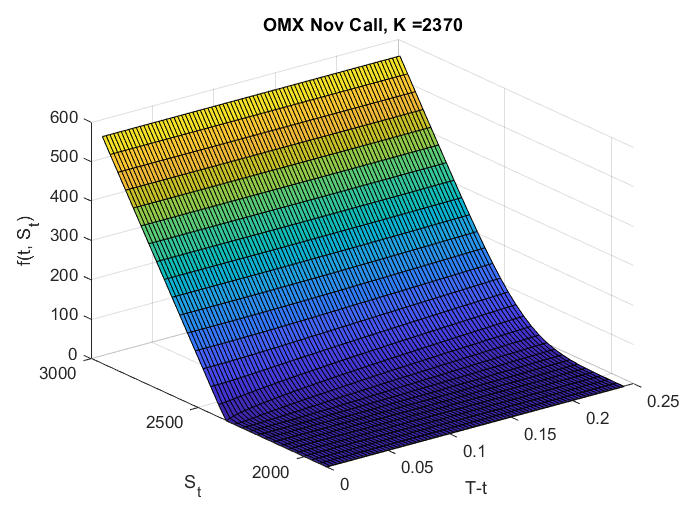

C_FDM = 62.3369

delta_FDM = 0.5045

C_SIncr = zeros(20,1);
C_tIncr = zeros(20,1);

for i = 1:20
    C_SIncr(i) = solver(M+i, N,   Sl, Su, theta, K, T, ...
                        vol, r, S0, Call, randCall, false);

    C_tIncr(i) = solver(M,   N+i, Sl, Su, theta, K, T, ...
                        vol, r, S0, Call, randCall, false);

delta_BSM = 0.5089

end

figure();
plot((M+1):(M+20), C_SIncr);
line((M+1):(M+20),C*ones(20,1),"col","red");
title("Refining the grid in S-direction"); 
xlabel("M"); 
ylabel("Price of option");
figure();
plot((N+1):(N+20), C_tIncr); title("Refining the grid in t-direction");
line((N+1):(N+20),C*ones(20,1),"col","red");
xlabel("N"); 
ylabel("Price of options");

The oscilations in the first plot can be attributed to the effect of the boundary conditions at $t=T$ as, depending on if the spacing of nodes, an even or odd number of nodes will end up respectively out of the money, explaining the zig-zaggy behaviour.

This implementation does also suffer some numerical drawbacks. A way to robustify the solver is introducing the change of variable $X_t = \ln{S_t}$ and correspondingly, $H(t,x)=f(t,e^x)$. This yields the following modified PDE:


$$\frac{\partial H(t,x)}{\partial t} + \left( r - \frac{\sigma^2}{2} \right)\frac{\partial H(t,x)}{\partial x} + \frac{\sigma^2}{2}\frac{\partial^2 H(t,x)}{\partial x^2} - rH(t,x) = 0$$


which has the nice property that the coefficients are now all constants (compared to the original PDE where they depend of $S_t$).

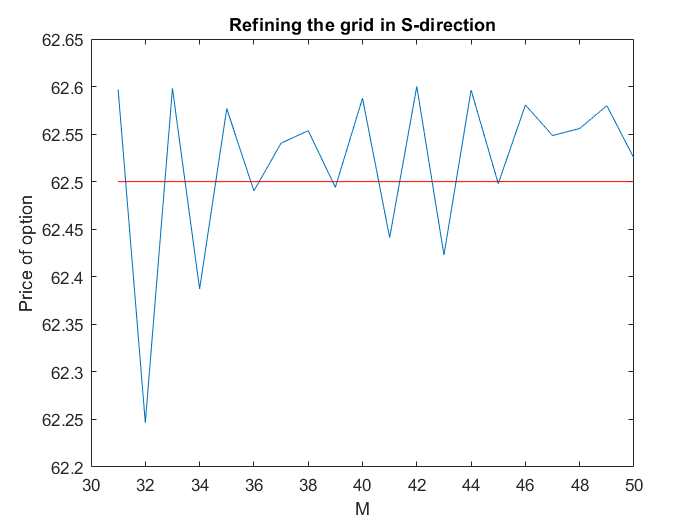

[C_ABR, delta_ABR] = solver_ABR(M, N, log(Sl), log(Su), theta, K, T, vol, r, ...
                                log(S0), ABR_Call, randABR_Call, true)

Let's first analyse the speed of convergence, for the cases $\theta=1$ (explicit FDM), $\theta = 0.5$ (Crank-Nicholson) and $\theta = 0$ (implicit FDM) with the new method, by varying the grid spacing in one variable at a time as before.

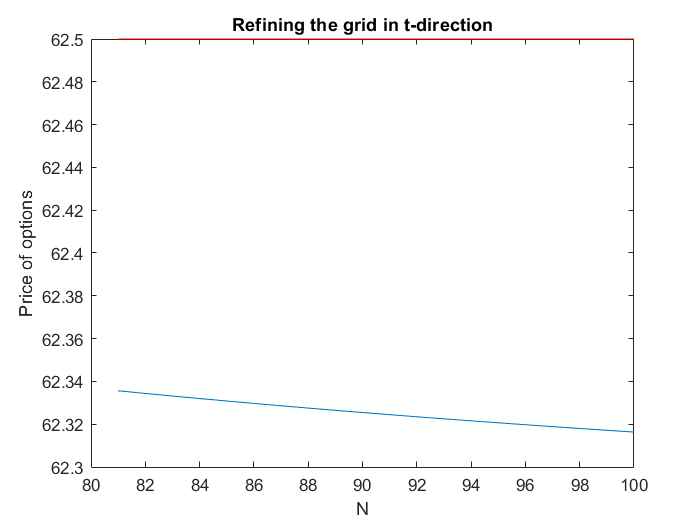

thetaVals = 0:0.5:1;
C_SIncr_ABR = zeros(20,3);
C_tIncr_ABR = zeros(20,3);

M = 36; % Good approximation according to the plot

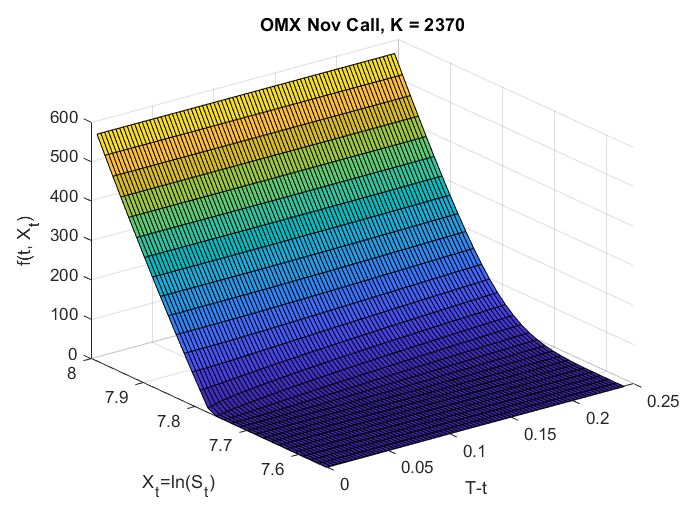

C_ABR = 62.5361

delta_ABR = 0.5446


cnt = 1;
figure();
len = 25;
for i = 1:3
    for j = 1:len

        C_SIncr_ABR(j,i) = solver_ABR(M+j, N,   log(Sl), log(Su), ...
            thetaVals(i), K, T, vol, r, log(S0), ABR_Call, randABR_Call, false);
        C_tIncr_ABR(j,i) = solver_ABR(M  , N+j, log(Sl), log(Su), ...
            thetaVals(i), K, T, vol, r, log(S0), ABR_Call, randABR_Call, false);
    end
    % Plot convergence
    subplot(3,2,cnt),   plot((M+1):(M+len), C_SIncr_ABR(:,i)); 
    title("S-direction when \theta=" + thetaVals(i)); 
    line((M+1):(M+len),C*ones(len,1),"col","red");
    subplot(3,2,cnt+1), plot((N+1):(N+len), C_tIncr_ABR(:,i)); 
    title("t-direction when \theta=" + thetaVals(i)); 
    line((N+1):(N+len),C*ones(len,1),"col","red");
    cnt = cnt+2;
end

It can be shown that for $\theta=1$, the method can become unstable, which can be seen in the downmost left figure. The theoretical limit of stability is given by $\sigma^2 \leq \frac{\Delta x^2}{\Delta t}$. This is examined below for an option with the same properties as before, only changing the maturity to $T-t=10Y$.

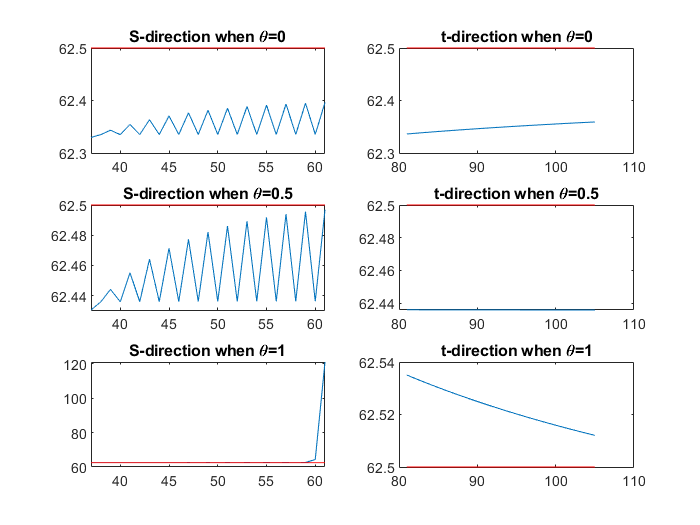

stable = 1;
M_test = 30;
N_test = N;
C_10y = BS_call(S0, K, r, vol, 10); % Analytical price for T = 10Y

while stable
   % Modify S_l och S_u considering new time
   [C_test,~] = solver_ABR(M_test, N_test, log(0.5*Sl), log(2*Su), ...
       1, K, 10, vol, r, log(S0), ABR_Call, randABR_Call, false);
   disp([M_test, C_test])
   if (C_test < 0.8*C_10y || C_test > 1.2*C_10y ) 
       %Unstable if price starts diverging
       stable = 0;
   else
       M_test = M_test + 1; % grow M (reduce delta_X^2/delta_T)
   end

end

Comparing the theoretical limit with the one obtained in this analysis shows that they are consistant.

lim = [(N_test-1)*(log(2*Su)-log(0.5*Sl))^2/(10*(M_test-1)^2), vol^2]

The demonstration shows that the method works reasonably well for the case of a plain vanilla call option. Any european option can however be valued, by just modifying the payoff function and the boundary values entered in the FDM solver. Below, Asset or Nothing and Cash or Nothing options, as well as plain vanilla options are valued with the implicit and explicit method, and the errors compared to the theoretical pricing formulas, which are:

- Cash or Nothing: $e^{-rT} \mathcal{N}(d_2)$

- Asset or Nothing: $S_t \mathcal{N}(d_1)$

with $d_1$ and $d_2$ defined as before, are measured.

M = 60;
N = 100;
[CoN_impl, ~] = solver_ABR(M, N, log(Sl), log(Su), 0, K, T, vol, r, ...
                           log(S0), ABR_CoN,  randABR_CoN,  true);
[AoN_impl, ~] = solver_ABR(M, N, log(Sl), log(Su), 0, K, T, vol, r, ...
                           log(S0), ABR_AoN,  randABR_AoN,  true);
[CoN_expl, ~] = solver_ABR(M, N, log(Sl), log(Su), 1, K, T, vol, r, ...
                           log(S0), ABR_CoN,  randABR_CoN,  false);
[AoN_expl, ~] = solver_ABR(M, N, log(Sl), log(Su), 1, K, T, vol, r, ...
                           log(S0), ABR_AoN,  randABR_AoN,  false);
[C_impl,   ~] = solver_ABR(M, N, log(Sl), log(Su), 0, K, T, vol, r, ...
                           log(S0), ABR_Call, randABR_Call, false);

CoN_BSM = exp(-r*T)*normcdf(d2(S0, K, r, vol, T));
AoN_BSM =        S0*normcdf(d1(S0, K, r, vol, T));


   30.0000  408.8203

   31.0000  408.0328

   32.0000  408.8340

   33.0000  408.1533

   34.0000  408.8454

   35.0000  408.2525

   36.0000  408.8549

   37.0000  408.3350

   38.0000  408.8629

   39.0000  424.5407

   1.0e+03 *

    0.0400    1.8439



lim =     0.0174    0.0186


% Absolute percentage error
CoN_err = 100*abs([CoN_impl, CoN_expl]-CoN_BSM)/CoN_BSM 
 AoN_err = 100*abs([AoN_impl, AoN_expl]-AoN_BSM)/AoN_BSM
Call_err = 100*abs([C_impl, C_ABR]-C)/C

The results show how the pricing errors are larger for the exotic options, possibly owning to the discontinuity around $S_T=K$ which is visible in the plots above. This could quite possibly lead to worse approximations of the derivative close to that region, thus leading to higher errors.

## Functions used in the script

### Steffensen's Method for Root Finding

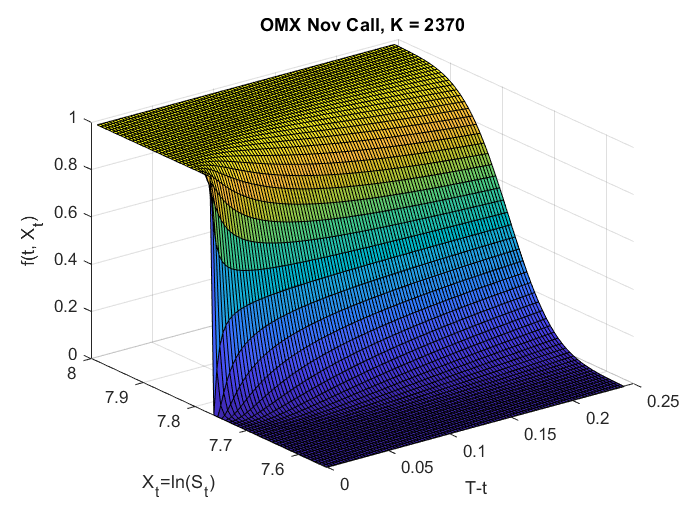

function [root] = Steffe(f,x0,tol,iter)

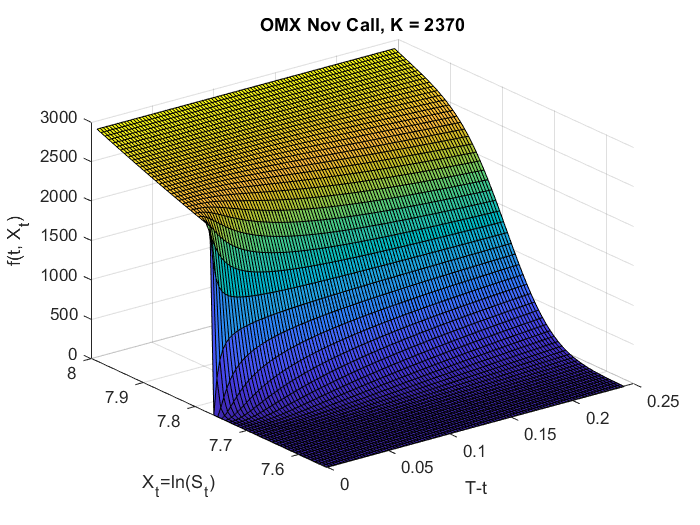

%% Steffensen method for finding roots of a function f(x)


   xVals = zeros(iter+1,1);
%  save the initial guess
   xVals(1) = x0;
%% Perform Steffensen for a fixed number of iterations
   for k = 1:iter
      fk  = f(xVals(k));
      fxf = f(xVals(k) + fk);
      xVals(k+1) = xVals(k) - fk^2/(fxf-fk);

      % check the stopping condition
      stopCond = abs(f(xVals(k+1)));
      if stopCond < tol

CoN_err =     3.7266    3.6999


         xVals = xVals(1:k+1);

AoN_err =     3.5214    3.5093


         break;

Call_err =     0.2308    0.0577


      end
   end
 root = xVals(end);
end

### Thomas Algorithm for LU-decomposing Tridiagonal Matrices

function [L,U] = thomas(A)
% Decomposing A=LU for tridiagonal square matrices A using Thomas Algorithm

     n  = length(A);
   for j = 1:n-1
      A(j+1,j) = A(j+1,j)/A(j,j); %L-component
      A(j+1,j+1) = A(j+1,j+1) - A(j+1,j)*A(j,j+1); %diagonal U-component
   end

   U = triu(A);
   L = eye(n) + tril(A,-1);
end

### Backward/Forward-substitution for Solving the LU-factorised System

function x = LUsolve(L, U, rhs)
    % Solves the system L*U*x = rhs through forward and backward substitution
    
    n = length(L);
    c = zeros(n,1);
    c(1) = rhs(1);
    
    % L*c = rhs
    for i = 2:n
        c(i) = rhs(i)-L(i,i-1)*c(i-1);
    end
    
    % Ux = c
    x= zeros(n,1);
    x(end) = c(end)/U(n,n);
    
    for i = n-1:-1:1
        x(i) = (c(i)-U(i,i+1)*x(i+1))/U(i,i);
    end
end

### The "Ordinary" Black-Scholes PDE solver

function [C_FDM, delta] = solver(M, N, Sl, Su, theta, K, T, ...
                                 vol, r, S0, payoff_f, ubound_f, plt)
% Returns todays price and an approximate option-delta
% As well as a plot of the price function
% by solving the Black-Scholes PDE with FDM 

    %% Solver Parameters
    deltaT = T/(N-1);
    deltaS = (Su-Sl)/(M-1);
    
    S = linspace(Sl, Su, M)'; % All points (incl. boundaries)
    
    grid = zeros(M,N);
    
    % Boudnary values at vid t=T (payoff)
    grid(:,N) = payoff_f(S,K);
    
    %% Create the matrices A (for Ax=b) and B (to make the vector b)
    main_diag  =    -(1-theta)*(vol*S(2:end-1)/deltaS).^2 -r -deltaT^-1;
    lower_diag = 0.5*(1-theta)*( -r*S(3:end-1)/deltaS + (vol*S(3:end-1)/deltaS).^2);
    upper_diag = 0.5*(1-theta)*(  r*S(2:end-2)/deltaS + (vol*S(2:end-2)/deltaS).^2);
    
    A = diag(main_diag,0) + diag(upper_diag,1) + diag(lower_diag,-1);
    
    m_diag  =  0.5*theta*(  r*S(2:end-1)/(deltaS) - (vol*S(2:end-1)/deltaS).^2);
    u_diag  =      theta*(vol*S(2:end-1)/deltaS).^2 - deltaT^-1;
    uu_diag = -0.5*theta*(  r*S(2:end-1)/(deltaS) + (vol*S(2:end-1)/deltaS).^2);
    
    B = zeros(M-2,M);
    
    for i = 1:(M-2)
        B(i,i)   = m_diag(i);
        B(i,i+1) = u_diag(i);
        B(i,i+2) = uu_diag(i);
    end
    
    % LU-facrotise A 
    % A tridiagonal, can use Thomas-algoritm
    [L, U] = thomas(A); 
    
    %% Solve for interior points
    % interior points
    for i = (N-1):-1:1
        
        % Boundary values
        grid(1,i) = 0;
        grid(M,i) = ubound_f(S(M), K, r, T-(i-1)*deltaT); %S(M) - K*exp(r*(T-(i-1)*deltaT));
        
        % Right hand side (f_i+1 terms)
        rhs = B*grid(:,i+1);
        
        % Move boundary values to rhs
        rhs(1)   = rhs(1)   -0.5*(1-theta)*(-r*S(2)/deltaS   + ...
                            (vol*S(2)/deltaS)^2)  *grid(1,i); 
        rhs(end) = rhs(end) -0.5*(1-theta)*( r*S(M-1)/deltaS + ...
                            (vol*S(M-1)/deltaS)^2)*grid(M,i); 
    
        % Solve system for interior points f_i and store in grid
        grid(2:M-1,i) = LUsolve(L, U, rhs);
    
    end
    
    % Interpolate price today with cubic spline
    C_FDM = spline(S, grid(:,1),S0);
    
    %% Approximate delta, given FDM-discretisation
    % Find node index closest to S = S0
    [~,idx] = min(abs(S-S0));
    delta = (1-theta)*(grid(idx+1,1) - grid(idx-1,1))/(2*deltaS) + ...
                theta*(grid(idx+1,2)-grid(idx-1,2))/(2*deltaS);
    
    %% Plot f(t, S_t)
    if plt
        figure();
        [pltT, pltS] = meshgrid(T:-deltaT:0, Sl:deltaS:Su);
        surf(pltT, pltS, grid);
        xlabel("T-t"), ylabel("S_t"), zlabel("f(t, S_t)")
        title("OMX Nov Call, K =" + K)
    end
end

### The Andersen, Brotherton-Ratcliffe Method for Solving the PDE

function [C_FDM, delta] = solver_ABR(M, N, xl, xu, theta, K, T, vol, r, X0, payoff_f, ubound_f, plt)
    % Returns todays price and an approximate option-delta
    % As well as a plot of the price function
    % by solving the Black-Scholes PDE with FDM 
    % and the change of variable X = ln(S)
    % as proposed in Andersen, Brotherton-Ratcliffe (1997)

    %% Solver Parameters
    deltaT = T/(N-1);
    deltaX = (xu-xl)/(M-1);
    
    X = linspace(xl, xu, M)'; % All points (incl. boundaries)
    
    grid = zeros(M,N);
    
    % Boudnary values at vid t=T (payoff)
    grid(:,N) = payoff_f(X,K);
    
    %% Create the matrices A (for Ax=b) and B (to make the vector b)
    main_diag  =    -(1-theta)*(vol/deltaX).^2 -r -deltaT^-1;
    lower_diag = 0.5*(1-theta)*(-(r-0.5*vol^2)/deltaX + (vol/deltaX).^2);
    upper_diag = 0.5*(1-theta)*( (r-0.5*vol^2)/deltaX + (vol/deltaX).^2);
    
    A = diag(main_diag*ones(M-2,1),0) + diag(upper_diag*ones(M-3,1),1) + ...
        diag(lower_diag*ones(M-3,1),-1);
    
    m_diag  =  0.5*theta*(  (r - 0.5*vol^2)/(deltaX) - (vol/deltaX).^2);
    u_diag  =      theta*(vol/deltaX).^2 - deltaT^-1;
    uu_diag = -0.5*theta*(  (r - 0.5*vol^2)/(deltaX) + (vol/deltaX).^2);
    
    B = zeros(M-2,M);
    
    for i = 1:(M-2)
        B(i,i)   = m_diag;
        B(i,i+1) = u_diag;
        B(i,i+2) = uu_diag;
    end
    
    % LU-facrotise A 
    % A tridiagonal, can use Thomas-algoritm
    [L, U] = thomas(A); 
    
    %% Solve for interior points
    % interior points
    for i = (N-1):-1:1
        
        % Boundary values
        grid(1,i) = 0;
        %exp(X(M)) - K*exp(r*(T-(i-1)*deltaT));
        grid(M,i) = ubound_f(X(M),K,r,T-(i-1)*deltaT);
        
        % Right hand side (f_i+1 terms)
        rhs = B*grid(:,i+1);
        
        % Move boundary values to rhs
        rhs(1)   = rhs(1)   -0.5*(1-theta)*(-(r - 0.5*vol^2)/deltaX   + ...
                  (vol/deltaX)^2)*grid(1,i); 
        rhs(end) = rhs(end) -0.5*(1-theta)*( (r - 0.5*vol^2)/deltaX   + ...
                  (vol/deltaX)^2)*grid(M,i); 
        
        % Solve system for interior points f_i and store in grid
        grid(2:M-1,i) = LUsolve(L, U, rhs);
        
    end
    
    % Interpolate price today with cubic spline
    C_FDM = spline(X, grid(:,1),X0);
    
    %% Approximate delta, given FDM-discretisation
    % Find node index closest to S = S0
    [~,idx] = min(abs(X-X0));
    delta = exp(-X0)*((1-theta)*(grid(idx+1,1) - grid(idx-1,1))/(2*deltaX) + ...
                          theta*(grid(idx+1,2)-grid(idx-1,2))/(2*deltaX));
    
    %% Plot f(t, X_t)
    if plt
        figure();
        [pltT, pltX] = meshgrid(T:-deltaT:0, xl:deltaX:xu);
        surf(pltT, pltX, grid);
        xlabel("T-t"), ylabel("X_t=ln(S_t)"), zlabel("f(t, X_t)")
        title("OMX Nov Call, K = " + K)
    end
end

## References

Andersen, Leif and Rupert Brotherton-Ratcliffe. “The equity option volatility smile: an implicit finite-difference approach.” *Journal of Computational Finance* 1 (1997): 5-37.

Lee, W. T. "Tridiagonal Matrices: Thomas Algorithm". [http://www.industrial-maths.com/ms6021_thomas.pdf](http://www.industrial-maths.com/ms6021_thomas.pdf) 

Wikipedia - The Free Encyclopedia. "Steffensen's Method". [https://en.wikipedia.org/wiki/Steffensen%27s_method](https://en.wikipedia.org/wiki/Steffensen%27s_method) 

Wikipedia - The Free Encyclopedia. "Black-Scholes Model". [https://en.wikipedia.org/wiki/Black%E2%80%93Scholes_model](https://en.wikipedia.org/wiki/Black%E2%80%93Scholes_model) 